%%用于后处理 得到muapt的cov，放电频率等统计数据
%%24-04 by 康亦铭
M=1;L=1;T=3;
PT = [selected{1}.pulses selected{2}.pulses];
muap= [selected{1}.muaps selected{2}.muaps];
for i=1:length(PT)
    pt=PT{i};
    dif=diff(pt);
    m=mean(dif);
    sigma=std(dif);
    isi{i}=dif(find(abs(dif-m)<3*sigma));
    CoV{i}=std(isi{i})/mean(isi{i});
    MAD_PT{i}=mad(isi{i});
end
sampfeqUS=2000;
for i=1:length(PT)
    freq{i}=sampfeqUS/mean(isi{i});
end

调看每个MUAP

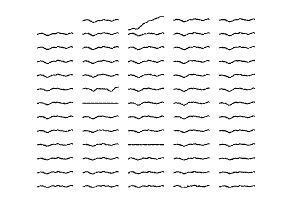


which2show=8;
figure;

plotArrayPotential(muaparray{which2show},1,1);

% tn4AP=['CKC-M' num2str(M) 'L' num2str(L) 'T' num2str(T) '-#' num2str(which2show)];
% title(tn4AP);

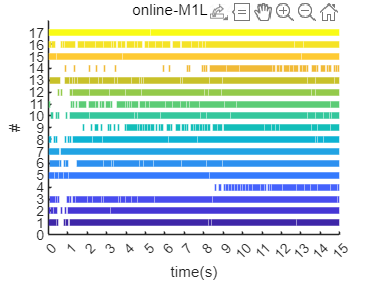

%muapt图

pic=draw_PluseTime(PT,2000,1,20,1);
tn4AP=['online-M' num2str(M) 'L' num2str(L) 'T' num2str(T) 'to1'];
title(tn4AP);